# Lab #03

Load simulated hospital data

clear
clc
    
load hospital.mat

Firstly, lets plot weight data

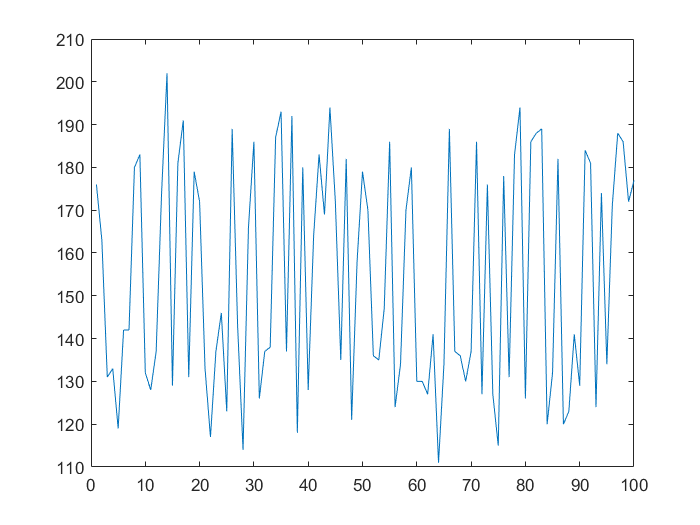

weightsAll=hospital.Weight;
plot(weightsAll);

When we analyze this plot we obtain no usefull information

Now, let's see the histogram

h1=histogram(weightsAll,'BinWidth',5)   

h1 =   Histogram with properties:

             Data: [100×1 double]
           Values: [2 4 7 9 13 11 5 2 0 1 2 2 8 6 11 11 5 0 1]
          NumBins: 19
         BinEdges: [110 115 120 125 130 135 140 145 150 155 160 165 170 175 180 185 190 195 200 205]
         BinWidth: 5
        BinLimits: [110 205]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


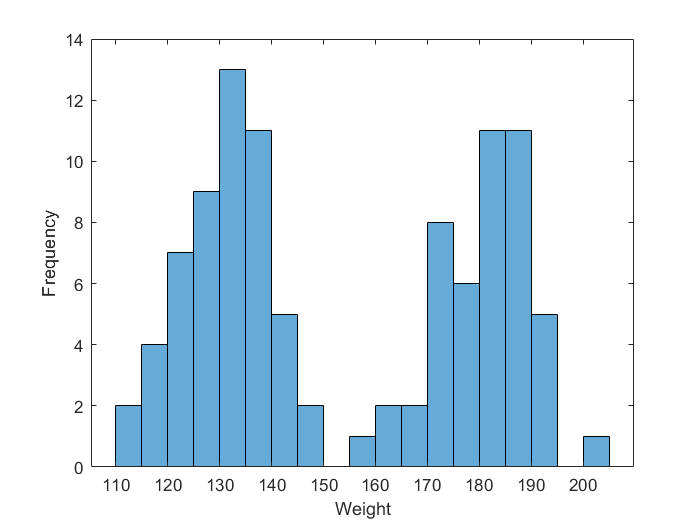

xlabel('Weight')
ylabel('Frequency')

Clearly we have two group of data. 

We can assume that gender makes difference in the data.

So split this data by gender. Then plot the histograms for each gender.

weightsFemale=hospital.Weight(hospital.Sex=='Female');
h2=histogram(weightsFemale,'BinWidth',5)   

h2 =   Histogram with properties:

             Data: [53×1 double]
           Values: [2 4 7 9 13 11 5 2]
          NumBins: 8
         BinEdges: [110 115 120 125 130 135 140 145 150]
         BinWidth: 5
        BinLimits: [110 150]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


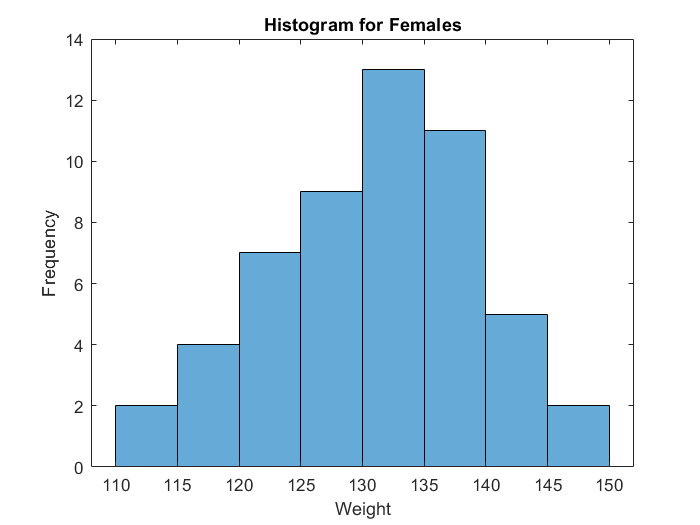

xlabel('Weight')
ylabel('Frequency')
title('Histogram for Females')


weightsMale=hospital.Weight(hospital.Sex=='Male');
h3=histogram(weightsMale,'BinWidth',5)   

h3 =   Histogram with properties:

             Data: [47×1 double]
           Values: [1 2 2 8 6 11 11 5 0 1]
          NumBins: 10
         BinEdges: [155 160 165 170 175 180 185 190 195 200 205]
         BinWidth: 5
        BinLimits: [155 205]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


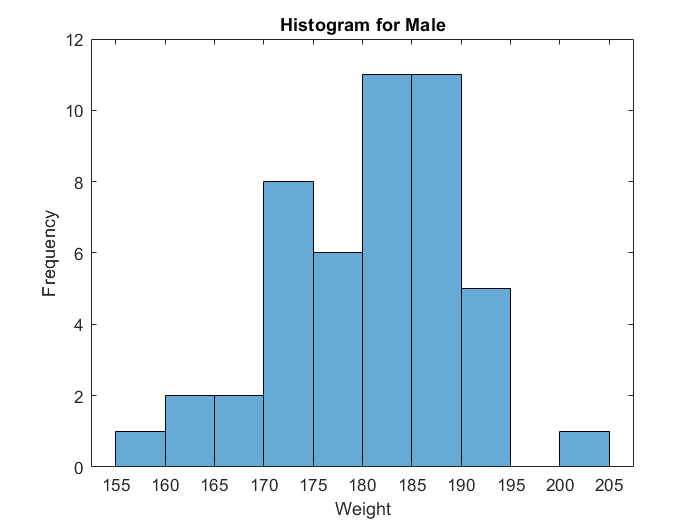

xlabel('Weight')
ylabel('Frequency')
title('Histogram for Male')

Now calculate standard deviation, mean and pdf. 

Then, plot histogram (Normalization->pdf) and pdf

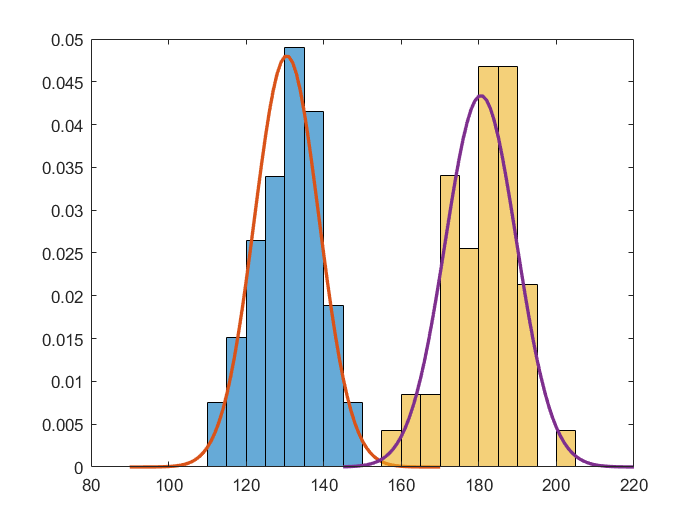

stdWeightFemale=std(weightsFemale);
meanWeightFemale=mean(weightsFemale);

stdWeightMale=std(weightsMale);
meanWeightMale=mean(weightsMale);

x1 = 90:1:170;
f1 = exp(-(x1-meanWeightFemale).^2./(2*stdWeightFemale^2))./(stdWeightFemale*sqrt(2*pi));

x2 = 145:1:220;
f2 = exp(-(x2-meanWeightMale).^2./(2*stdWeightMale^2))./(stdWeightMale*sqrt(2*pi));

histogram(weightsFemale,'Normalization',"pdf","BinWidth",5)
hold on
plot(x1,f1,'LineWidth',2)

histogram(weightsMale,'Normalization',"pdf","BinWidth",5)
plot(x2,f2,'LineWidth',2)
hold off

Alternatively, instead of using a long formula for calculating f (pdf),

we can use matlab's functions **makedist** and **pdf**

pd1 = makedist('Normal','mu',meanWeightFemale,'sigma',stdWeightFemale);
F1 = pdf(pd1,x1)

F1 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0009    0.0012    0.0017    0.0023    0.0031    0.0040    0.0053    0.0067    0.0085    0.0105    0.0129    0.0156    0.0185    0.0217    0.0251    0.0286    0.0321    0.0355    0.0387    0.0416    0.0440    0.0460    0.0473    0.0480    0.0479    0.0472    0.0459    0.0439    0.0414    0.0385    0.0353    0.0319    0.0284



pd2 = makedist('Normal','mu',meanWeightMale,'sigma',stdWeightMale);
F2 = pdf(pd2,x2)

F2 =     0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0004    0.0005    0.0007    0.0009    0.0012    0.0016    0.0022    0.0028    0.0036    0.0045    0.0057    0.0070    0.0086    0.0104    0.0124    0.0147    0.0171    0.0198    0.0225    0.0254    0.0282    0.0310    0.0337    0.0362    0.0384    0.0403    0.0418    0.0428    0.0433    0.0433    0.0428    0.0419    0.0404    0.0386    0.0364    0.0339    0.0312    0.0284    0.0255    0.0227    0.0199    0.0173    0.0148



histogram(weightsFemale,'Normalization',"pdf","BinWidth",5)
hold on
plot(x1,F1,'LineWidth',2)

histogram(weightsMale,'Normalization',"pdf","BinWidth",5)
plot(x2,F2,'LineWidth',2)
hold off